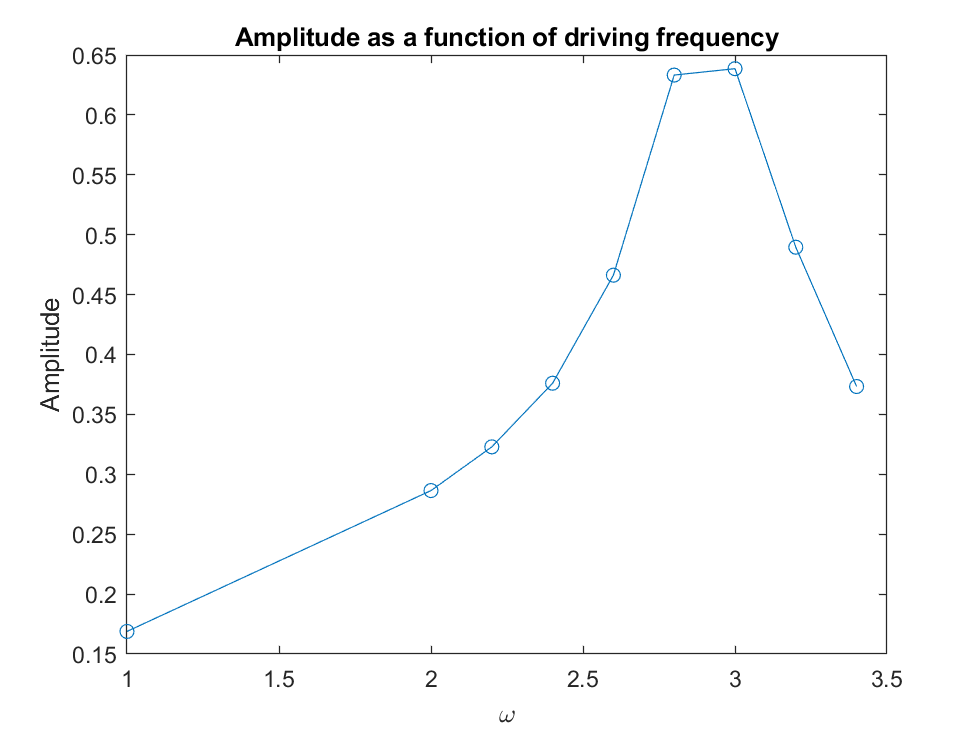

g = 9.81;
omega2 = 9;
R = g/omega2;
gamma = 0.5;
theta0 = 0;
thetad0 = 0;
A = [];
omega_array = [1,2,2.2,2.4,2.6,2.8,3.0,3.2,3.4];
for i=1:length(omega_array)
     [t,w] = pendulum_damp_driven(R,theta0,thetad0,gamma,omega_array(i));
     ind5 = find(w(:,2)>=0 & circshift(w(:,2), [-1 0]) <=0);
     A(i) = max(w(ind5,1));
     ind5 = zeros;
end
plot(omega_array,A,'o-')
xlabel('\omega')
ylabel('Amplitude')
title('Amplitude as a function of driving frequency')

(a) As omega increases from 1 to 3, the Amplitude also increases. After that, the Amplitude decreases as omega increases.

Yes, the max A is reached at omega=3, which is close to omega0.

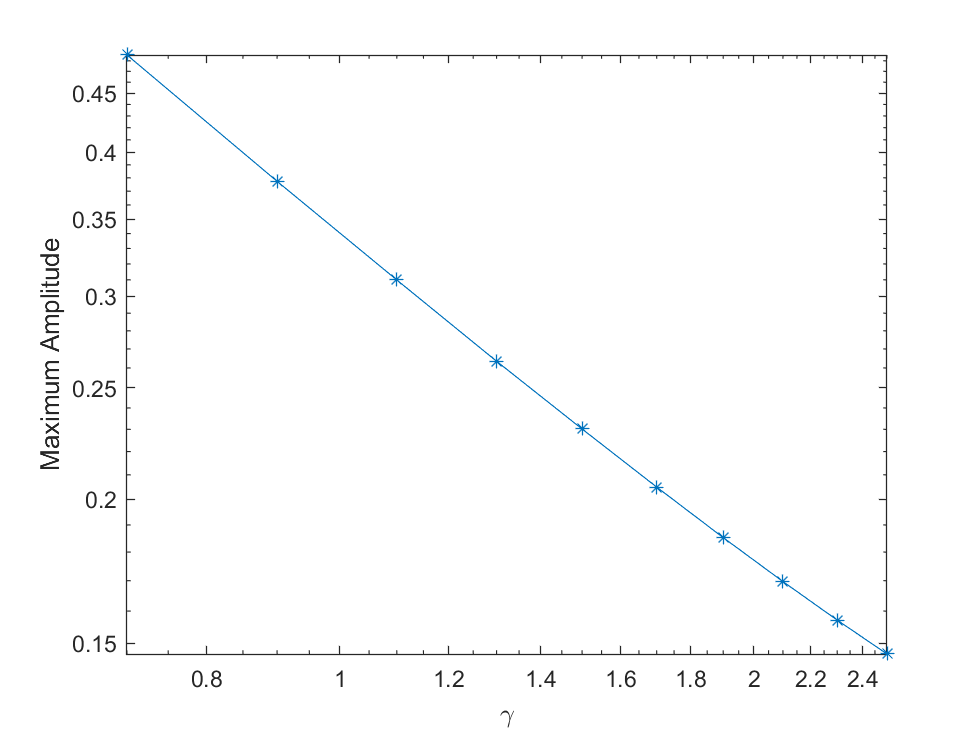

for j=1:10
    gamma(j) = j/5+0.5;
    for i = 1:100  
        omega_array(i) = 3/100*i+1.5;
        [t,w] = pendulum_damp_driven(R,theta0,thetad0,gamma(j),omega_array(i));
        ind5 = find(w(:,2)>=0 & circshift(w(:,2), [-1 0]) <=0);
        A(i) = max(w(ind5,1));
        ind5 = zeros;
    end
    [Amax(j),nn(j)] = max(A);
    wmax(j) = omega_array(nn(j));
    [dd2(j),n2(j)] = min(abs(A(nn(j):end)-(1/sqrt(2))*Amax(j)));
    [dd1(j),n1(j)] = min(abs(A(1:nn(j))-(1/sqrt(2))*Amax(j)));
    deltaw(j) = omega_array(n2(j)+nn(j)-1)-omega_array(n1(j));
    omega_array = zeros;
    A = zeros;
end
figure
loglog(gamma,Amax, '*-')
xlabel('\gamma')
ylabel('Maximum Amplitude')

It seems that the Amax ~ 1/gamma. While delta_omega/omega_max increases as gamma increases, and the speed looks like log to gamma according to the plot below.

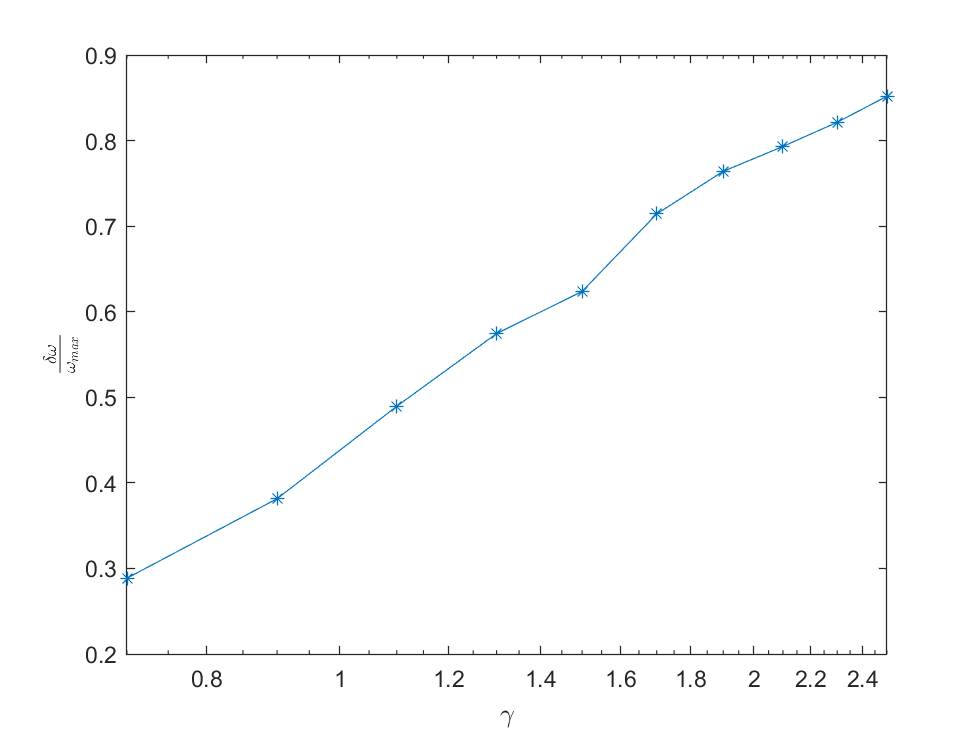

figure
semilogx(gamma,deltaw./wmax, '*-')
xlabel('\gamma')
ylabel('$\frac{\delta\omega}{\omega_{max}}$','interpreter','latex')